# Computer Assignment 4:  Robot Trajectory Optimization

Finn Vehlhaber and Leonardo Pedroso

In this assignment we learn how to incorporate discretized differential equations into an optimization problem and solve it with the Matlab Optimization Toolbox. For questions (a) to (c) refer to the handout.

**Run the sections one by one by clicking into the respective code window and hitting "Run Section". Sentences highlighted in bold give instructions on how to complete the given code. Code lines like this need to be completed by you:**

% ----- complete code here
% (incomplete code here)
% -----

Clean up script

clear; close all; clc

**(c)** Write MATLAB code to implement the optimization problem using quadprog, with parameters N and T that can be set by the user.

**Parameters**

% ----- complete code here
T = 5;
N = 40;
% -----
% Time increment
h = T/(N+1);

**Initial and final conditions**

% ----- complete code here
% Initial state
x0 = 0;
y0 = 0;
v0 = 4;
w0 = 0;
% Final state
xf = -1;
yf = 2;
vf = 0;
wf = 0;
% -----

**Recall the syntax of quadprog: **

% [x,fval,exitflag,output,lambda]=quadprog(H,f,A,b,Aeq,beq,l,u)

Type    >>  `help quadprog `for more details and examples. 

Below assemble matrices/vectors:

- H, f (portray the objective function)

- A, b (linear inequality constraints)

- Aeq,beq (linear equality constraints)

- l,u (lower and upper bounds on decision variables)

**Objective function:**

% ----- complete code here
size_d = 4*N + 2*(N+1) %size of the dimension vector 
H = zeros(size_d,size_d);
%d = [x_n, y_n, v_n, w_n, Q_(N+1), P_(N+1) -> size of the matrix is thus
%the above
for n = 1:N+1
    %quadprog halves the value, therefore the value in the matrix is 2 
  H(4*N+n,4*N+n) = 2; %index for P set to 2, to program the quadratic value
  H(4*N+N+1+n,4*N+N+1+n) = 2; %idem for index of Q
end 
f = zeros(4*N+2*(N+1),1); %in the objective function there are no constant values
% -----

**Linear inequality constraints:**

% ----- complete code here

A = zeros(N,size_d); %for each time step 0 t/m N the equation must hold
b = zeros(N,1); 
%x_n + y_n <= 3 must hold meaning 
for n = 1:N-1
  A(n,n) = 1; %selecting x values
  A(n,N+n) = 1; %selecting y values
  b(n) = 3; %right side of the equation
end
% -----

**Linear equality constraints:**

% ----- complete code here
Aeq = zeros(4*(N+1),size_d);
beq = zeros(4*(N+1),1);

%setting intial and final state constraints 
%the order that these are put into the matrix does not matter, all of them
%just need to be set
% n = 0
Aeq(1,1) = 1;
Aeq(1,2*N+1) = -h;       
Aeq(2,N+1) = 1;
Aeq(2,3*N+1) = -h;  
Aeq(3,2*N+1) = 1;
Aeq(3,4*N+1) = -h;
Aeq(4,3*N+1) = 1;
Aeq(4,4*N+N+1+1) = -h;
beq(1) = x0;
beq(2) = y0;
beq(3) = v0;
beq(4) = w0;
% n = N
Aeq(5,N) = -1;                             
Aeq(6,2*N) = -1;                           
Aeq(7,3*N) = -1;
Aeq(7,4*N+N+1) = -h;     
Aeq(8,4*N) = -1;
Aeq(8,4*N+2*(N+1)) = -h; 
beq(5) = -xf+h*vf;
beq(6) = -yf+h*wf;
beq(7) = -vf;
beq(8) = -wf;
% n = 1...N-1
j = 8; %the first and final 4*2 equality constraints have already been set
for n = 1:N-1
  % At discrete instant n
  % Position equality constraints (x)
  j = j + 1; 
  Aeq(j,n) = -1;
  Aeq(j,n+1) = 1;
  Aeq(j,2*N+n+1) = -h;
  beq(j) = 0;
  % Position equality constraints (y)
  j = j + 1;
  Aeq(j,N+n) = -1;
  Aeq(j,N+n+1) = 1;
  Aeq(j,3*N+n+1) = -h;
  beq(j) = 0;
  % Velocity equality constraints (x)
  j = j + 1;
  Aeq(j,2*N+n) = -1;
  Aeq(j,2*N+n+1) = 1;
  Aeq(j,4*N+n+1) = -h;
  beq(j) = 0;
  % Velocity equality constraints (y)
  j = j + 1;
  Aeq(j,3*N+n) = -1;
  Aeq(j,3*N+n+1) = 1;
  Aeq(j,4*N+N+1+n+1) = -h;
  beq(j) = 0;
end
% -----

**Lower and upper bounds:**

% ----- complete code here
lb =[];
ub =[];
% -----

**Solve with **`quadprog`

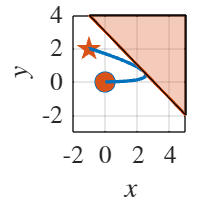

% Call quadprog
[d, fval, exitflag, output, lambda] = quadprog(H,f,A,b,Aeq,beq,lb,ub);
% Plot trajectory
plot_traj(d,x0,y0,xf,yf,N);

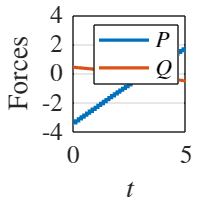

% Plot inputs
plot_PQ(d,N,h,T);

**(e)** Run your implementation above for:

- N = 40; T = 5

- N = 40; T = 10

Explain: Do the results make sense? Why? 

Sol: Longer horizon -> Final position can be achieved with lower forces -> longer trajectory

**(f)** Experiment with increasing values for N. Comment.

Sol: Larger N -> better approximation of the differential equations, allows for changing the forces applied more often, solution varies for different N if N are low

**(g)** Suppose the forces P(t) and Q(t) should satisfy the condition $$ P^2(t) + Q^2(t) \leq F^2_\text{max}$$.  Then `quadprog` cannot be used anymore, but `fmincon` should be used instead. Explain.

**(h) **Change the Matlab implementation to call `fmincon` to include this additional condition, with parameters N, T, and $$F_\text{max}$$  that can be set by the user. Which initial point do you provide to `fmincon`?

**Recall the syntax of quadprog: **

%[x,fval,exitflag,output,lambda,grad,hessian] = fmincon(fun,d0,A,b,Aeq,beq,lb,ub,nonlcon)

Type    >>  `help fmincon `for more details and examples. 

Below we just need to assemble:

- fun (objective function)

- nonlcon (nonlinear constraints)

- d0 initail concition to fmincon

**Parameters**

% ----- complete code here
Fmax = 3;
% -----

**fun**

Complete the code of `objfun(d,N,T)` at the end of the script

fun = @(d) objfun(d,N,T);

**nonlcon**

Complete the code of `objfun(d,N,T)` at the end of the script

nonlcon = @(d) nonlconFmax(d,N,Fmax);

**Initial condition**

% ----- complete code here 
d0 = d;
% -----

**Solve with fmincon**

% Call fmincon
opts = optimoptions('fmincon','MaxFunEvals',20e3);
[dfmincon,fval,exitflag,output,lambda] = fmincon(fun,d0,A,b,Aeq,beq,lb,ub,nonlcon,opts);


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


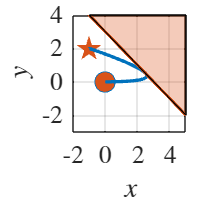

% Plot trajectory
plot_traj(dfmincon,x0,y0,xf,yf,N);

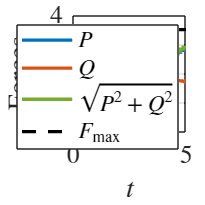

% Plot inputs
plot_PQ_wmax(dfmincon,N,h,T,Fmax);

**(i) **Set N = 40 and $$ F_\text{max} = 3 $$, and run your implementation for T = 5 and T = 10. Compare the calculated paths with question (e).  If the `fmincon` solver stopped prematurely, experiment with changing the algorithm settings. 

**(j)** Experiment with algorithm settings and also with problem size (N).

Auxiliary functions

function f = objfun(d,N,T)
% ----- complete code here
     f = 0;
     for n = 1:1:N+1
       Pn = d(4*N+n);
       Qn = d(4*N+N+1+n);
       f = f+(Pn^2 + Qn^2)*T/(N+1);
     end
% -----     
end

function [g,h] = nonlconFmax(d,N,Fmax)
% ----- complete code here
     for n = 1:1:N+1
       Pn = d(4*N+n);
       Qn = d(4*N+N+1+n);
       g(n) = (Pn^2 + Qn^2)/(Fmax^2) - 1;
     end
h=[];
% -----  
end 

function plot_traj(d,x0,y0,xf,yf,N)
    x = [x0;d(1:N);xf];
    y = [y0;d(N+1:2*N);yf];
    figure('Position',4*[0 0 144 144]); % Nice aspect ratio for double column
    hold on;
    grid on;
    box on;
    set(gca,'FontSize',15);
    set(gca,'TickLabelInterpreter','latex') % Latex style axis
    % Plot initial and final points
    scatter([x0],[y0],150,'o','MarkerFaceColor',[0.8500, 0.3250, 0.0980]);
    scatter([xf],[yf],200,'pentagram','MarkerFaceColor',[0.8500, 0.3250, 0.0980]);
    % Plot trajectory 
    plot(x,y,'LineWidth',2,'Color',[0, 0.4470, 0.7410]);
    % Plot trajectory constraints
    N_points = 1000;
    x_points = [-2:(5+2)/(N_points-1):5];
    plot(x_points,3-x_points,'LineWidth',2,'Color',[0.8500, 0.3250, 0.0980]);
    fill([5 -1 5 5],[-2 4 4 -2],[0.8500, 0.3250, 0.0980],'FaceAlpha',0.3)
    ylabel('$y$','Interpreter','latex');
    xlabel('$x$','Interpreter','latex');
    xlim([-2 5]);
    ylim([-3 4]);
    hold off;
end

function plot_PQ(d,N,h,T)
    P = [d(4*N+1:4*N+N+1);d(4*N+N+1)];
    Q = [d(4*N+N+1+1:4*N+N+1+N+1);d(4*N+N+1+N+1)];
    figure('Position',4*[0 0 144 144]); % Nice aspect ratio for double column
    hold on;
    grid on;
    box on;
    set(gca,'FontSize',15);
    set(gca,'TickLabelInterpreter','latex') % Latex style axis
    % Plot trajectory 
    t = h*(0:N+1)';
    stairs(t,P,'LineWidth',2,'Color',[0, 0.4470, 0.7410]);
    stairs(t,Q,'LineWidth',2,'Color',[0.8500, 0.3250, 0.0980]);
    legend({'$P$','$Q$'},'Location','northeast','Interpreter','latex');
    % Plot trajectory constraints
    ylim([-4 4]);
    xlim([0,T]);
    ylabel('Forces','Interpreter','latex');
    xlabel('$t$','Interpreter','latex');
    hold off;
end

function plot_PQ_wmax(d,N,h,T,Fmax)
    P = [d(4*N+1:4*N+N+1);d(4*N+N+1)];
    Q = [d(4*N+N+1+1:4*N+N+1+N+1);d(4*N+N+1+N+1)];
    figure('Position',4*[0 0 144 144]); % Nice aspect ratio for double column
    hold on;
    grid on;
    box on;
    set(gca,'FontSize',15);
    set(gca,'TickLabelInterpreter','latex') % Latex style axis
    % Plot trajectory 
    t = h*(0:N+1)';
    stairs(t,P,'LineWidth',2,'Color',[0, 0.4470, 0.7410]);
    stairs(t,Q,'LineWidth',2,'Color',[0.8500, 0.3250, 0.0980]);
    stairs(t,sqrt(P.^2+Q.^2),'LineWidth',2,'Color',[0.4660, 0.6740, 0.1880]);
    plot([0 T],Fmax*[1 1],'--','LineWidth',2,'Color',[0 0 0]);
    legend({'$P$','$Q$','$\sqrt{P^2+Q^2}$','$F_\mathrm{max}$'},'Location','northeast','Interpreter','latex');
    % Plot trajectory constraints
    ylim([-4 4]);
    xlim([0,T]);
    ylabel('Forces','Interpreter','latex');
    xlabel('$t$','Interpreter','latex');
    hold off;
end
